% ECE490 Lab 3 
%% Clears all the workspace
clc
clear
%%

load('molecular_absorption.mat') % load the file which contains frequency absorption data

% The file above loads 'f' and 'k'

%% Section 1 - Finding the frequency of operation 
dummy_variable = 1;
freq_2_use = [];
k_2_use = [];
for i = 1:length(f)
    if (f(i) >= 100e9)&&(f(i)<=1.5e12)
       freq_2_use(dummy_variable) = f(i);
       k_2_use(dummy_variable) = k(i);
       dummy_variable = dummy_variable + 1;
    end
end 


%% Finding the distances
r = [1  10  100]; % distances

%% Section 2 - Absorption Loss 
for i = 1:length(r)
    for j = 1:length(freq_2_use)
    ab_loss(i,j) = 1./(exp(-k_2_use(j).*r(i)));
    ab_loss_db (i,j) = 10*log10(ab_loss(i,j));
    end
end

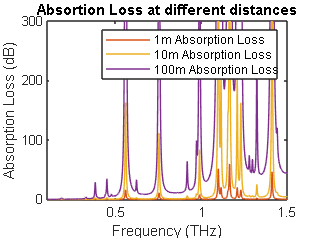



%% Section 3 - plotting the absorption loss
figure(1)
box on; 
h1 = plot(freq_2_use/(1e12), ab_loss_db(1,:)); % plots the absorption loss for the first link 
hold on; 
h2 = plot(freq_2_use/(1e12),ab_loss_db(2,:)); 
h3 = plot(freq_2_use/(1e12),ab_loss_db(3,:));% plot the absorption loss in dB for the third link distance 
legend([h1 h2 h3], {'1m Absorption Loss', '10m Absorption Loss ', '100m Absorption Loss '},'Location','northeast') % give your own names which are self explanatory
ylim ([0 300]) % a limit on the range of the absorption loss 
xlim([0.1, 1.5])  % another limit on the range of the frequencies 
title('Absortion Loss at different distances')
xlabel('Frequency (THz)') 
ylabel('Absorption Loss (dB)')

%% Section 4 - Spreading Loss
c_const = 3e8; % speed of light 
wavelength = c_const./freq_2_use ; % find the wavelength from the frequencies.. 
A_eff = wavelength.^2./(4.*pi); % effective aperture of a dipole
 for i = 1:length(r)
     for j = 1:length(A_eff)
         spr_loss(i,j) = 4.*pi.*r(i).^2./(A_eff(j));
         spr_loss_db(i,j) = 10*log10(spr_loss(i,j)); % find the spreading loss in dB
         path_loss_db(i,j) = spr_loss_db(i,j) + ab_loss_db(i,j); % total path loss in dB
     end
 end

 

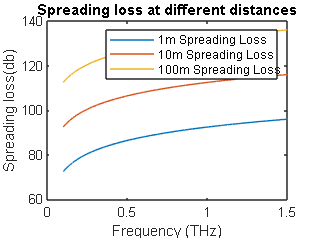

%% Section 5 - Plotting the Spreading and Path Loss
 figure(2)
   h4 = plot(freq_2_use/(1e12),spr_loss_db(1,:)); % spreading loss in dB for first link distance 
    hold on 
   h5 = plot(freq_2_use/(1e12),spr_loss_db(2,:)); % spreading loss in dB for second link distance 
   h6 = plot(freq_2_use/(1e12),spr_loss_db(3,:)); % spreading loss in dB for third link distance  
    legend([h4 h5 h6], {'1m Spreading Loss','10m Spreading Loss','100m Spreading Loss'},'Location','northeast')
title('Spreading loss at different distances')
xlabel('Frequency (THz)')
ylabel('Spreading loss(db)')
hold off;

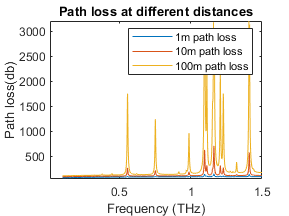


 figure(3)
  h7 = plot(freq_2_use/(1e12),path_loss_db(1,:)); %path loss in dB for first link distance 
    hold on 
    h8 = plot(freq_2_use/(1e12),path_loss_db(2,:)); %path loss in dB for second link distance 
   h9 = plot(freq_2_use/(1e12),path_loss_db(3,:)); %path loss in dB for third link distance  
    hold off;
legend([h7 h8 h9], {'1m path loss','10m path loss','100m path loss'},'Location','northeast')
title('Path loss at different distances')
xlabel('Frequency (THz)')
ylabel('Path loss(db)')

%% Section 6 - Comparison between the measured and simulated path losses
    %Q2
    load('channel.mat')
    %%
    freq_3_use = [];
    k_3_use = [];
     dummy_variable = 1;
    for i = 1:length(freq_2_use)
    if (freq_2_use(i) >= 0.98e12)&&(freq_2_use(i) <= 1.07e12) 
       freq_3_use(dummy_variable) = freq_2_use(i);
       k_3_use(dummy_variable) = k_2_use(i);
       dummy_variable = dummy_variable + 1;
    end
    end
wavelength_2 = c_const./freq_3_use;
A_eff_2 = wavelength_2.^2./(4.*pi);
r_new = [16e-2]; % new link distance 
    for j = 1:length(freq_3_use)
    ab_loss_2(1,j) = 1./(exp(-k_3_use(j).*r_new));
    ab_loss_db_2 (1,j) = 10*log10(ab_loss_2(1,j));
    spr_loss_2(1,j) = 4.*pi.*r_new.^2./(A_eff_2(j));
    spr_loss_db_2(1,j) = 10*log10(spr_loss_2(1,j));
    path_loss_db_2(1,j) = spr_loss_db_2(1,j)+ ab_loss_db_2(1,j);
    end


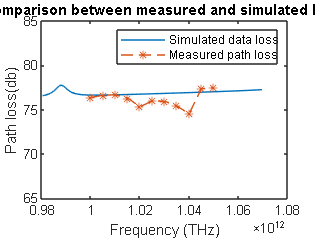

%% Section 7 - Plot and compare the two 
 figure(4)
    h10 = plot(freq_3_use, path_loss_db_2);
    hold on 
    h11 = plot(f,H, '--*'); % the measured values 
    ylim([65 85])
    legend([h10 h11], {'Simulated data loss', 'Measured path loss'},'Location','northeast')
    hold off;
title('A comparison between measured and simulated losses')
xlabel('Frequency (THz)')
ylabel('Path loss(db)')